clc;clear;close all;

% a) Read the csv files containing the time series of the average RGB values in the  facial region.(fps = 60)
run = readmatrix('run.csv');
sleep = readmatrix("sleep.csv");

% b) Normalize the data and apply bandpass filtering. (0.6Hz, 4Hz)
process_run = process_ppg(run);
process_sleep = process_ppg(sleep);

% c) Process the data in the three csv files using PCA or SVD method.
%PCA
run_pca = BestPca(process_run);
sleep_pca = BestPca(process_sleep);
% SVD
run_svd = BestSVD(process_run);
sleep_svd = BestSVD(process_sleep);

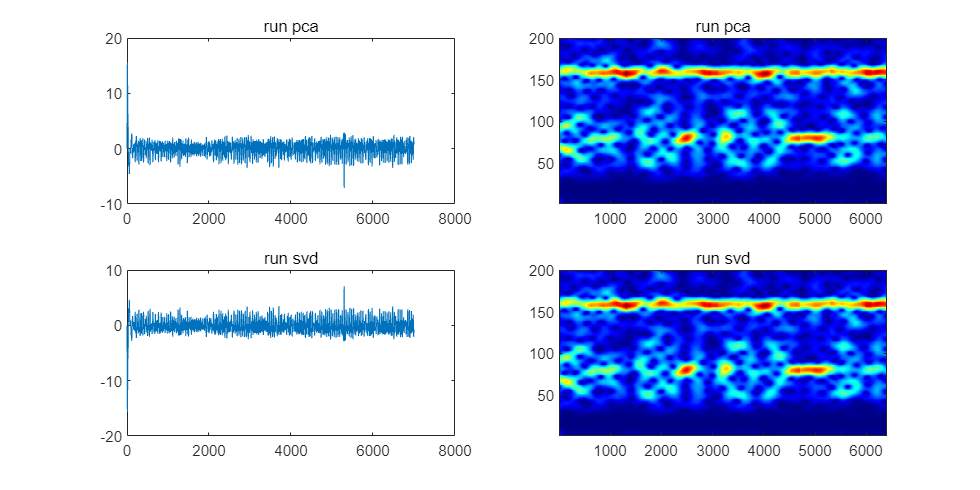

% d) Plot the PPG signal and the spectrogram using the function spec.
fs = 60;
[run_pca_spc, ~] = spec(run_pca',fs);
[sleep_pca_spc, ~] = spec(sleep_pca', fs);
[run_svd_spc, ~] = spec(run_svd', fs);
[sleep_svd_spc, ~] = spec(sleep_svd', fs);

figure, set(gcf, 'Position', [100 100 2000 1000]); colormap('jet');
subplot(2,2,1);
plot(run_pca);
title('run pca')
subplot(2,2,2);
imagesc(run_pca_spc(1:200,:)); set(gca,'YDir','normal');
title('run pca')
subplot(2,2,3);
plot(run_svd);
title('run svd')
subplot(2,2,4);
imagesc(run_svd_spc(1:200,:)); set(gca,'YDir','normal');
title('run svd')

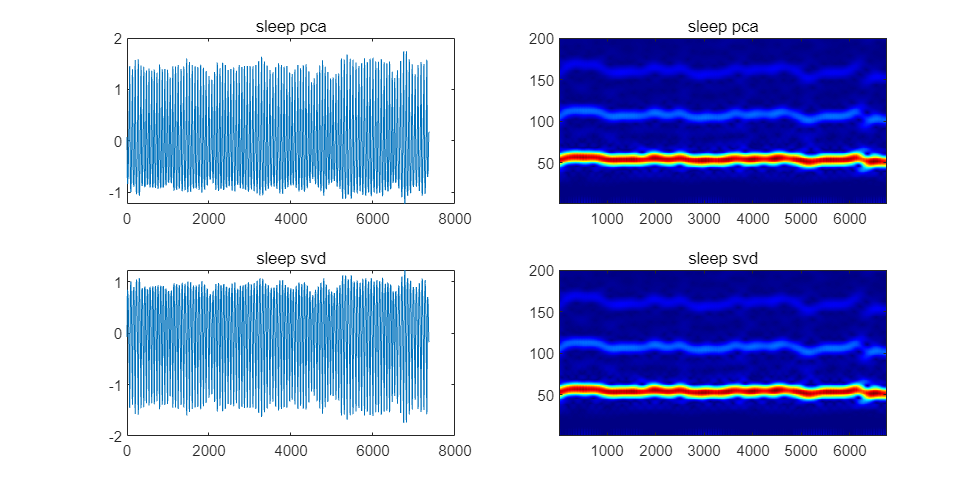

figure, set(gcf, 'Position', [100 100 2000 1000]); colormap('jet');
subplot(2,2,1);
plot(sleep_pca);
title('sleep pca')
subplot(2,2,2);
imagesc(sleep_pca_spc(1:200,:)); set(gca,'YDir','normal');
title('sleep pca')
subplot(2,2,3);
plot(sleep_svd);
title('sleep svd')
subplot(2,2,4);
imagesc(sleep_svd_spc(1:200,:)); set(gca,'YDir','normal');
title('sleep svd')

function [spc, rate] = spec(signal, fps)
% Input: pulse - 1xN pulse signal
% fps - 1x1 camera frame rate
% Output: spc - 1xM pulse specctrogram
% hr - 1xM heart rate signal
% define parameter
L = fps * 10;
S = zeros(size(signal,2)-L+1,L);
for idx = 1:size(signal,2)-L+1
p = signal(1,idx:idx+L-1);
S(idx,:) = (p-mean(p))/(eps+std(p));
end
S = S-repmat(mean(S,2),[1,L]);
S = S .* repmat(hann(L)',[size(S,1),1]);
S = abs(fft(S,fps*60,2));
spc = S(:,1:fps*60/2)';
[~, rate] = max(spc,[],1);
rate = rate - 1;
end

function filtered_RGB = process_ppg(data)
RGB = data(:,2:4);
%data whitening
normalized_RGB = (RGB - mean(RGB, 1)) ./ std(RGB, 0, 1);
%Filter
fs = 60;
nyq = 0.5 * fs;
low = 0.6 / nyq;
high = 4 / nyq;
[b, a] = butter(4, [low, high], 'bandpass');
filtered_RGB = filtfilt(b, a, normalized_RGB);
end

function best_pca = BestPca(filtered_RGB)
%PCA
[coeff, projected_signals, ~, ~, explained] = pca(filtered_RGB);
F = fft(projected_signals',[],2); 
S = abs(F(:,1:floor(end/2)-1)); 
snr = max(S,[],2)./(sum(S,2)-max(S,[],2)); 
[~, best_signal_idx] = max(snr);
best_pca = projected_signals(:, best_signal_idx);
end 

function best_svd = BestSVD(filtered_RGB)
[U, S_, V] = svd(filtered_RGB, 'econ');
projected_signals = filtered_RGB * V;
F = fft(projected_signals',[],2); 
S = abs(F(:,1:floor(end/2)-1)); 
snr = max(S,[],2)./(sum(S,2)-max(S,[],2)); 
[~, best_signal_idx] = max(snr);
best_svd = projected_signals(:, best_signal_idx);
end
